# MATLAB, The MATrix LABoratory

## Prehľad prostredia / Environment overview

Ľavý panel (Left pane)

- Current folder

Stredný panel (Middle pane)

- Editor, Command window

Pravý panel (Right pane)

- Workspace

Horné menu (Top menu)

- Run

- Run section

- Apps

## **Stránka predmetu**

[https://sites.google.com/stuba.sk/vgg/dsozb/general-info](https://sites.google.com/stuba.sk/vgg/dsozb/general-info) 

## Základné príkazy

Úloha: Vytvorte si 2 premenné a inicializujte ich náhodným číslom. Vykonajte ich vynásobenie, ktorý výsledok ako jediný vypíšete na konzolu.

## Basic commands

Task: Create 2 variables and initialize them with random number. Multiply these 2 variables and print out the result (don't print out first 2 variables being added).

% Riesenie / Solution
% naplnenie premennej s náhodno hodnotu v rozsahu (0,1)
var1 = rand();
var2 = rand();
%dsplay() -- zobrazenie hodnoty
display(var1 * var2);

    0.0220



## Maticové operácie

Úloha č.1: 

Vytvorte riadkový vektor *a* s hodnotami: 2; 3.5; 4.2; 5; -1.5

Vytvorte riadkový vektor *b* s hodnotami: -2; 3; -1.8; 1; 0.5

Vykonajte sčítanie dvoch vektorov po indexoch a vypíšte súčet čísel vo výslednom vektore.

Vykonajte vynásobenie týchto dvoch vektorov po indexoch a vypíšte štandardnú odchýlku výsledného vektora.

## Matrix operations

Task no.1: 

Create row vector a with following values: 2; 3.5; 4.2; 5; -1.5

Create row vector b with following values: -2; 3; -1.8; 1; 0.5

Add these two vectors by indices and print out the resulting vector.

Multiply these two vectors by indices and print out standard deviation of the resulting vector.

% Riesenie / Solution
% naplnenie premennej, novým stlpcovým vectorom
a = [2; 3.5; 4.2; 5; -1.5];
b = [-2; 3; 1.8; 1; 0.5];
display(a+b);

         0
    6.5000
    6.0000
    6.0000
   -1.0000



% zobraz vector, ktorý je standardnou odchylkou, výsledku nasobenia matíc A a B(ktorá bola transponovaná, pre umožnenie násobenia)
% pretože matice s rozmerm 5x1 a 5x1, sa nemôžu násobyť. Preto bolo
% potrebné jednu maticu transponovať, čo je prípustná operácia, kedže v
% zadaní bolo násobene vectorov bez špecifikovania typu vectorov (tj. riadkvé, stĺpcové).
display(std(a * transpose(b)));

    5.1276    7.6914    4.6148    2.5638    1.2819



Úloha č.2:

Vytvorte riadkový vektor *a* veľkosti 1x111 s hodnotami od 0 po 55 s krokom 0,5.

Vytvorte stĺpcový vektor *b* veľkosti 111x1 s hodnotami od 0 po 55 s krokom 0,5.

Vykonajte vynásobenie vektorov dvomi spôsobmi:

- a * b

- b * a

Porovnajte výsledok (je rovnaky?)

Task no.2:

Create row vector a with size 1x111 with values from 0 to 55 with step of 0.5

Create column vector b with size 1x111 with values from 0 to 55 with step of 0.5

Multiply these two vectors following ways:

- a * b

- b * a

Compare the results (are they equal ?):

% Riesenie / Solution
%naplnenie premennej s vectorom, v rozsahu 0 - 55, kedy rozdiel každeho
%dalšieho člena ood predošlého je 0.5, ciže n = 111
a = 0:.5:55;
%podobne ako predoslý vektor s rozdielom v tom, že výsledny vektor je ešte transponovaný:
b = a';

% vynásobenie týchto dvoch vektorov, v ich rôznom poradí:
mult1 = a * b

mult1 = 1.1243e+05

mult2 = b * a

mult2 = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0003    0.0005    0.0008    0.0010    0.0013    0.0015    0.0018    0.0020    0.0022    0.0025    0.0027    0.0030    0.0032    0.0035    0.0037    0.0040    0.0043    0.0045    0.0047    0.0050    0.0053    0.0055    0.0057    0.0060    0.0063    0.0065    0.0067    0.0070    0.0073    0.0075    0.0077    0.0080    0.0083    0.0085    0.0088    0.0090    0.0092    0.0095    0.0097    0.0100    0.0103    0.0105    0.0107    0.0110    0.0112    0.0115    0.0118


%zobraz vysledok porovnavania dvoch matíc
if isequal(mult1, mult2) == true
    disp("Sú rovnaké.");
else
    disp("Nie su rovnaké.");
end

Nie su rovnaké.


%výsledok je: Nie sú rovnaké.

Úloha č.3: (indexovanie)

Vytvorte si dve matice veľkosti 5x5 a inicializujte ich náhodnými číslami v intervale <0;5>

Vykonajte vynásobenie prvých troch stĺpcov prvej matice s 1,2,4 riadkom z druhej matice

Task no. 3:(indexing)

Crete two matrices of size 5x5 and initialize them with random values on interval <0;5>

Mulitply first 3 columns of first matrix with 1,2,4 row of the second matrix.

% Riesenie / Solution

%naplnenie premennej s náhodnimy čislami, v rozsahu <0, 5>:
%to je dosiahnute vynasobením základnej nahodnej hodnoty, z rozsahu (0,1) s 10,
% a následne upravenie týchto hôdnot, aby maximum bol <5, s operaciou modus
a = mod(rand(5) * 10, 5);
b = mod(rand(5) * 10, 5);

% naplnenie premennej, výsledkom nasobenia matíc, so špecifikáciou toho že:
    % matica A vchádza do operacie iba ako 5x3 1. a B ako 3x5 s indexami
    % jednotlívých stlpcov [1,2,4]
ab = a(:,[1 2 3]) * b([1 2 4],:);
display(ab);

ab =    19.5311   20.8877   11.9313   13.1688   29.0880
   11.8892   19.2205    9.2083   24.3976   25.1427
   18.3502   20.7982   18.0633   20.8481   25.7783
   13.8889   19.6964   13.5507   24.6308   24.6112
   10.0517   13.3413    9.6408   15.6167   16.7200


## **Grafy - vykresľovanie**

Úloha č.1:

Zobrazte základný sínusový signál na intervale <0;1> s krokom 0.01

Pomôcka: plot() 

Task no.1:

Display basic sine signal on interval <0;1> with step of 0.01

Hint: plot() 

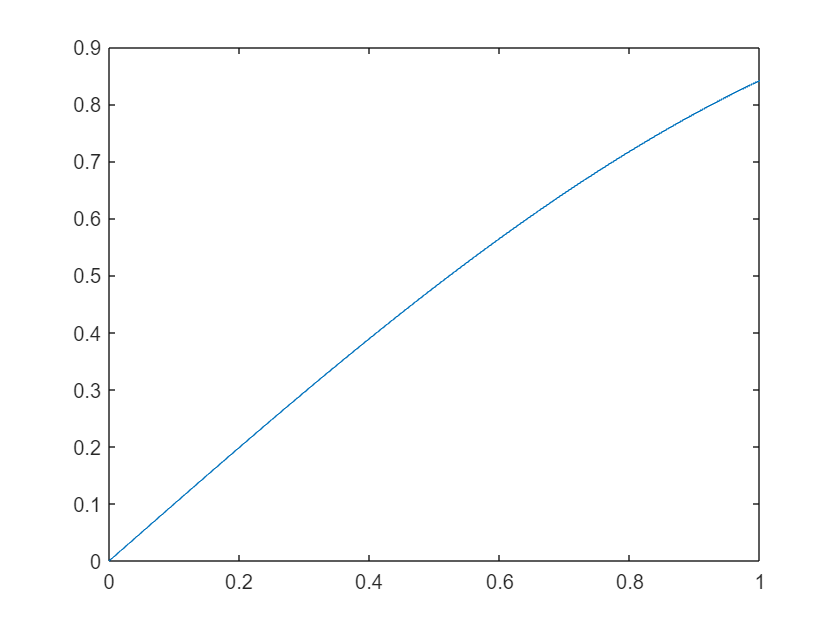

% Riesenie / Solution

%1. ako prvé naplnenie lubovolne novej premennej cielovým intervalom, tj.
%<0,1> s tým že rozdiel susedných hodnot vektora je 0.01:
x = 0:.01:1;

%na koniec táto premenná bola transformovaná do s funkciou sin() a následne
%zobrazená funkciou plot(), s tým že x os má rozsah 100 bodov
plot(x, sin(x));

Úloha č.2:

Pomenujte osi predošlej vizualizácie.

Task no.2:

Name axes of the chart created in previous step.

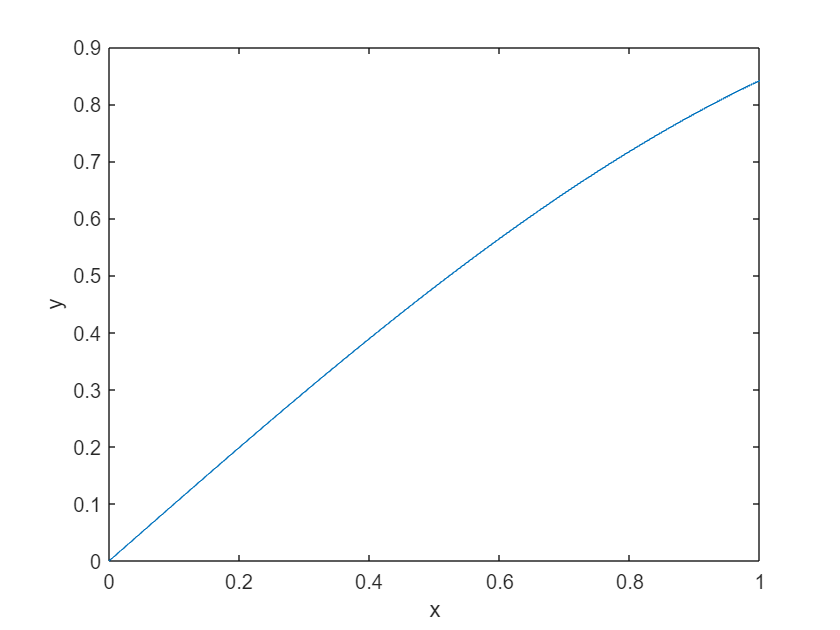

% Riesenie / Solution
%zadefinovanie osí posledneho zobrazeného grafu
xlabel("x");
ylabel("y");

Úloha č.3:

Vytvorte stĺpcový vektor s vypočítanými hodnotami funkcie sínus z predošlej úlohy a vynásobte ho tým istým, ale riadkovým vektorom (výsledok je matica)

Vizualizujte túto maticu funkciou: surf()

Task no.3:

Create column vector with values from sine fuction and multiply it by the transposed version of itself (result should be matrix).

Visualize this matrix with function: surf()

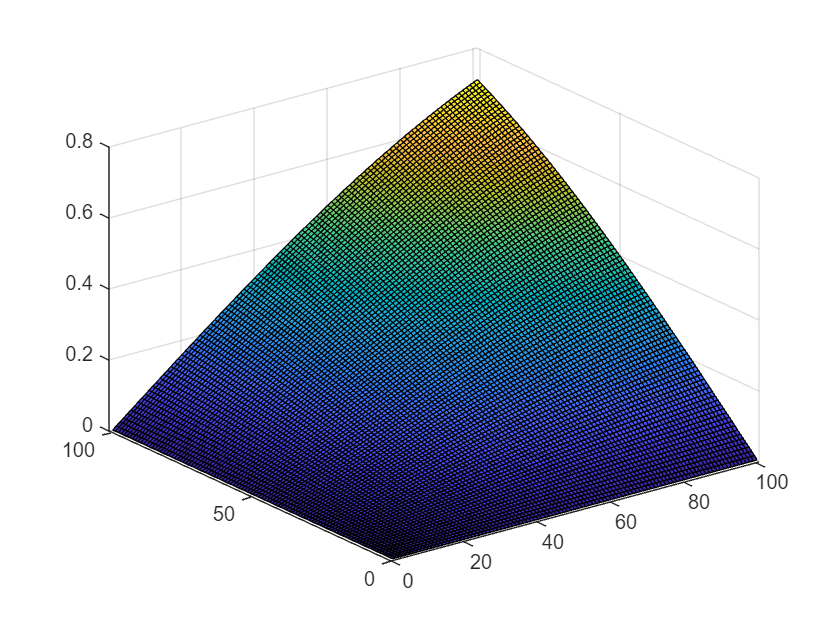

% Riesenie / Solution

% riadkový vektor, ktr. obsahuje hodnoty: s "vypočítanými hodnotami funkcie sínus z predošlej úlohy":
rowvec = sin(x);
% stĺpcový vektor, ktr. je v podstate, transponovaný predošlý, riadkový vektor:
columvec = rowvec';

% nasleduje vizualizácia, vyslednej matice, z násobenia stĺpcového a
% riadkového vektora:
surf(columvec * rowvec);